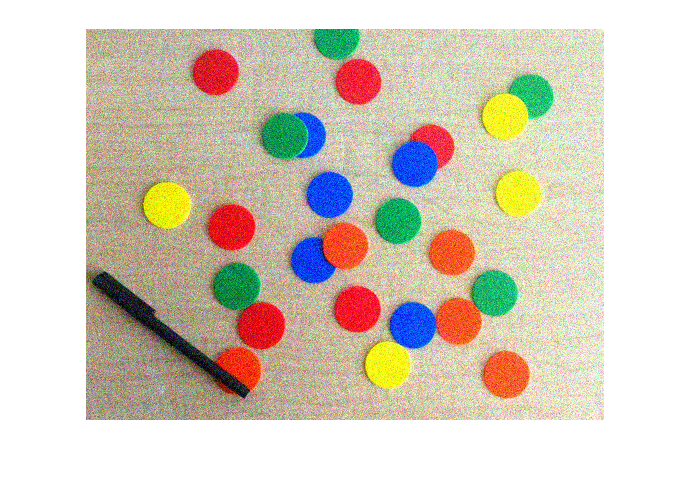

clc,clear,close all
I = imread("CFig3.png");
I = imnoise(I);
imshow(I)

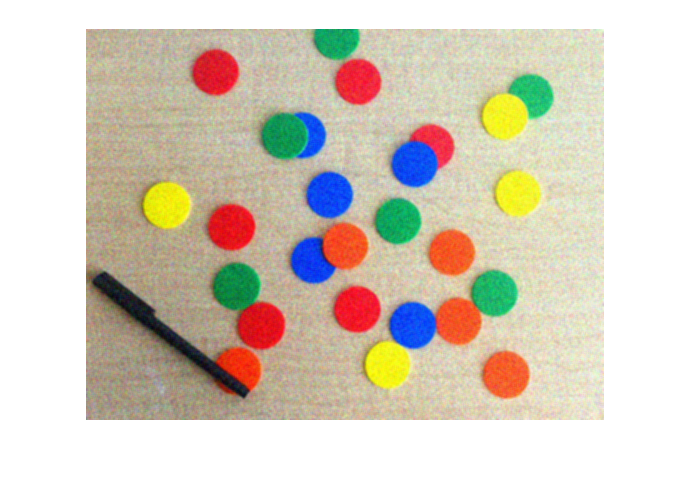

W = fspecial('average', 3); % 均值滤波器
fR = I(:,:,1);
fG = I(:,:,2);
fB = I(:,:,3);
fR_filtered = imfilter(fR, W, 'replicate');
fG_filtered = imfilter(fG, W, 'replicate');
fB_filtered = imfilter(fB, W, 'replicate');
I_filtered = cat(3, fR_filtered, fG_filtered, fB_filtered);
imshow(I_filtered)

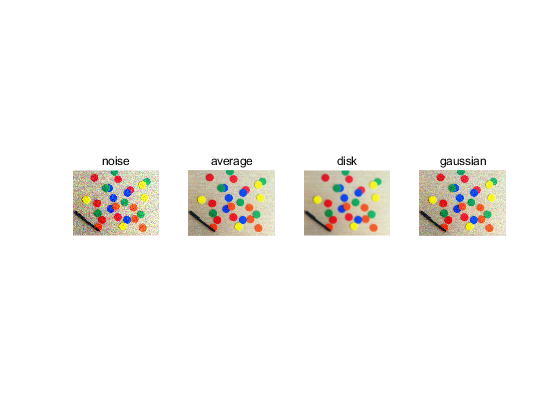

w1 = fspecial('average', 3); % 均值滤波器
w2 = fspecial('disk',5); % 圆形平均值滤波器
w3 = fspecial('gaussian'); % 高斯低通滤波器
figure,subplot(1,4,1),imshow(I),title('noise')
f1 = imfilter(I, w1, 'replicate');subplot(1,4,2),imshow(f1),title('average')
f2 = imfilter(I, w2, 'replicate');subplot(1,4,3),imshow(f2),title('disk')
f3 = imfilter(I, w3, 'replicate');subplot(1,4,4),imshow(f3),title('gaussian')

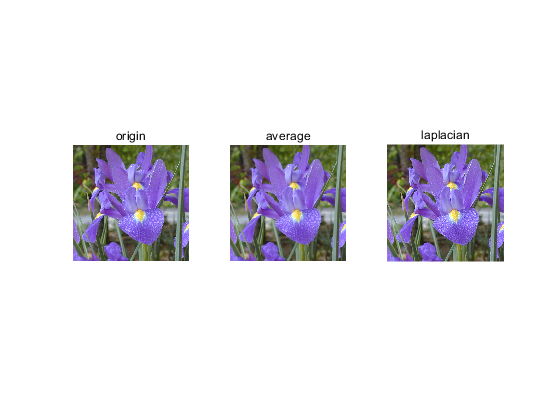

clc,clear,close all
I = imread("CFig0.tif");
subplot(1,3,1),imshow(I),title('origin')
W = fspecial('average', 3); % 均值滤波器
I = imfilter(I, W, 'replicate');
subplot(1,3,2),imshow(I),title('average')
H = fspecial('laplacian');
I = double(I);
lap = imfilter(I, H, 'replicate');
fen = imsubtract(I, lap);
subplot(1,3,3),imshow(uint8(fen)),title('laplacian')

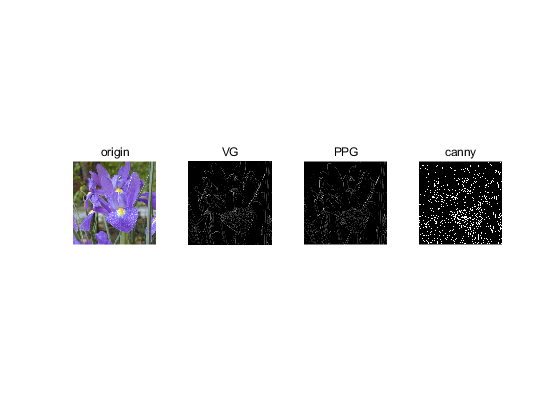

clc,clear,close all
I = imread("CFig0.tif");
[VG,A,PPG] = colorgrad(I, 0.1);
subplot(1,4,1),imshow(I),title('origin')
subplot(1,4,2),imshow(VG),title('VG')
subplot(1,4,3),imshow(PPG),title('PPG')
I = rgb2gray(I);
edge = edge(I, 'canny');
subplot(1,4,4),imshow(edge),title('canny')

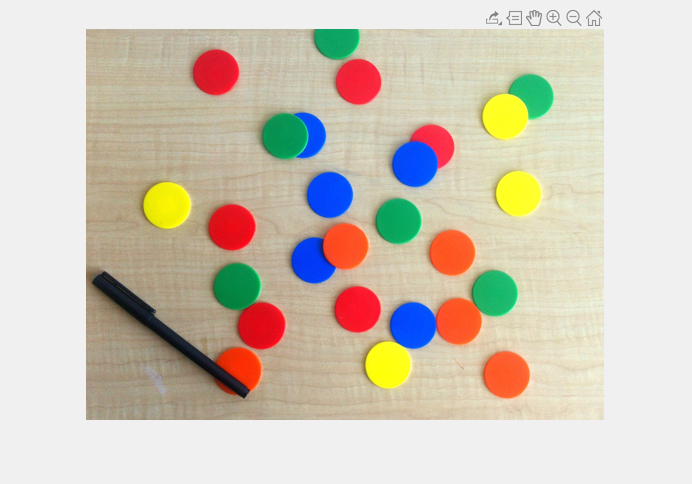

clc,clear,close all
f = imread("CFig3.png");
mask = roipoly(f);

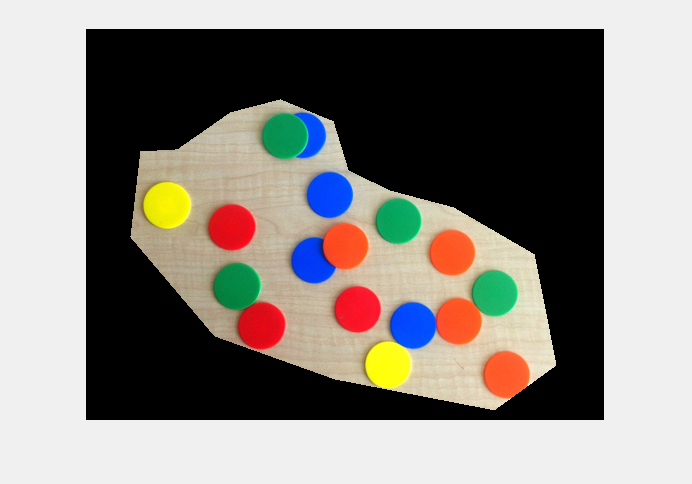

red = immultiply(mask, f(:, : , 1));
green= immultiply(mask, f(:, :, 2));
blue= immultiply(mask, f(:, :, 3));
g = cat(3, red, green, blue);
imshow(g)

[M, N, K] = size(g);
I = reshape(g, M * N, 3);
idx =find(mask);
I = double(I(idx, 1:3));
[C, m] = covmatrix(I)

C = 	1.0e+03 *

    5.7172    1.0407   -1.3370
    1.0407    3.3809    1.1928
   -1.3370    1.1928    3.8224


m =   179.1793
  159.6250
  135.7085


d = diag(C);
sd = sqrt(d)'

sd =    75.6119   58.1453   61.8252


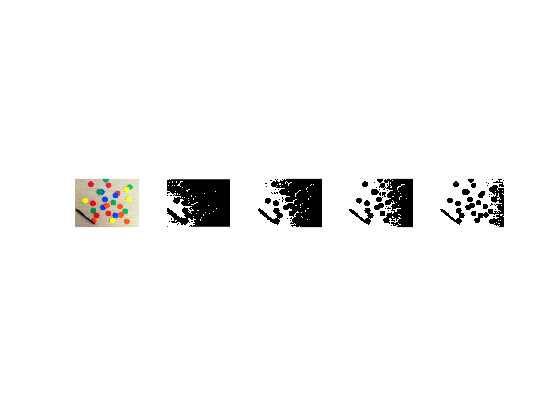

E25 = colorseg ('euclidean', f, 25, m);
E50 = colorseg ('euclidean', f, 50, m);
E75 = colorseg ('euclidean', f, 75, m);
E100 = colorseg ('euclidean', f, 100, m);
subplot(1,5,1),imshow(f)
subplot(1,5,2),imshow(E25)
subplot(1,5,3),imshow(E50)
subplot(1,5,4),imshow(E75)
subplot(1,5,5),imshow(E100)

close all
M25 = colorseg ('mahalanobis', f, 25, m);
M50 = colorseg ('mahalanobis', f, 50, m);
M75 = colorseg ('mahalanobis', f, 75, m);
M100 = colorseg ('mahalanobis', f, 100, m);
subplot(1,5,1),imshow(f)
subplot(1,5,2),imshow(M25)
subplot(1,5,3),imshow(M50)
subplot(1,5,4),imshow(M75)
subplot(1,5,5),imshow(M100)

function [VG,A,PPG]=colorgrad(f,T)
%COLORGRAD Computes the vector gradient of an RGB image. 
%   [VG, VA, PPG] = COLORGRAD(F, T) computes the vector gradient, VG, 
%   and corresponding angle array, VA, (in radians) of RGB image 
%   F. It also computes PPG, the per-plane composite gradient 
%   obtained by summing the 2-D gradients of the individual color  
%   planes. Input T is a threshold in the range [0, 1]. If it is 
%   included in the argument list, the values of VG and PPG are 
%   thresholded by letting VG(x,y) = 0 for values <= T and VG(x,y) = 
%   VG(x,y) otherwise. Similar comments apply to PPG.  If T is not 
%   included in the argument list then T is set to 0. Both output 
%   gradients are scaled to the range [0, 1].   
%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins 
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004 
%   $Revision: 1.6 $  $Date: 2003/11/21 14:27:21 $   
if  (ndims(f) ~= 3) || (size(f,3) ~=3)
    error('Input image must be RGB.');
end
% Compute the x and y derivatives of the three component images  
% using Sobel operators. 
sh=fspecial('sobel');
sv=sh';
Rx=imfilter(double(f(:,:,1)),sh,'replicate');
Ry=imfilter(double(f(:,:,1)),sv,'replicate');
Gx=imfilter(double(f(:,:,2)),sh,'replicate');
Gy=imfilter(double(f(:,:,2)),sv,'replicate');
Bx=imfilter(double(f(:,:,3)),sh,'replicate');
By=imfilter(double(f(:,:,3)),sv,'replicate');
%Compute the parameters of the vector gradient. 
gxx=Rx.^2+Gx.^2+Bx.^2;
gyy=Ry.^2+Gy.^2+By.^2;
gxy=Rx.*Ry+Gx.*Gy+Bx.*By;
A=0.5*(atan(2*gxy./(gxx-gyy+eps)));
G1=0.5*((gxx+gyy)+(gxx-gyy).*cos(2*A)+2*gxy.*sin(2*A));
% Now repeat for angle + pi/2. Then select the maximum at each point. 
A=A+pi/2;
G2=0.5*((gxx+gyy)+(gxx-gyy).*cos(2*A)+2*gxy.*sin(2*A));
G1=G1.^0.5;
G2=G2.^0.5;
% Form VG by picking the maximum at each (x,y) and then scale 
% to the range [0, 1]. 
VG=mat2gray(max(G1,G2));
% Compute the per-plane gradients. 
RG=sqrt(Rx.^2+Ry.^2);
GG=sqrt(Gx.^2+Gy.^2);
BG=sqrt(Bx.^2+By.^2);
% Form the composite by adding the individual results and 
% scale to [0, 1]. 
PPG=mat2gray(RG+GG+BG);
 
% Threshold the result. 
if nargin==2
    VG=(VG>T).*VG;
    PPG=(PPG>T).*PPG;
end
end

function [C, m] = covmatrix(X)
%COVMATRIX Computes the covariance matrix of a vector population.
%   [C, M] = COVMATRIX(X) computes the covariance matrix C and the
%   mean vector M of a vector population organized as the rows of
%   matrix X. C is of size N-by-N and M is of size N-by-1, where N is
%   the dimension of the vectors (the number of columns of X).
[K, n] = size(X);
X = double(X);
if n==1%
    C=0;
    m=X;
else
    %Compute an unbiased estimate of m
    m=sum(X,1)/K;
    %Subtract the mean from each row of X
    X=X-m(ones(K,1), :);
    %Computr an unbiased estimate of  C . Note that the produc is
    %X'*X because the vectors are rows of X
    C=(X'*X)/(K-1);
    m=m';%Convert to a column vector
end
end

function [X, R] = imstack2vectors(S, MASK)
%IMSTACK2VECTORS Extracts vectors from an image stack.
%   [X, R] = imstack2vectors(S, MASK) extracts vectors from S, which
%   is an M-by-N-by-n stack array of n registered images of size
%   M-by-N each (see Fig. 11.24). The extracted vectors are arranged
%   as the rows of array X. Input MASK is an M-by-N logical or
%   numeric image with nonzero values (1s if it is a logical array)
%   in the locations where elements of S are to be used in forming X
%   and 0s in locations to be ignored. The number of row vectors in X
%   is equal to the number of nonzero elements of MASK. If MASK is
%   omitted, all M*N locations are used in forming X.  A simple way
%   to obtain MASK interactively is to use function roipoly. Finally,
%   R is an array whose rows are the 2-D coordinates containing the
%   region locations in MASK from which the vectors in S were
%   extracted to form X.  

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.6 $  $Date: 2003/11/21 14:37:21 $

% Preliminaries.
[M, N, n] = size(S);
if nargin == 1
   MASK = true(M, N);
else
   MASK = MASK ~= 0;
end

% Find the set of locations where the vectors will be kept before
% MASK is changed later in the program.
[I, J] = find(MASK);
R = [I, J];

% Now find X.

% First reshape S into X by turning each set of n values along the third
% dimension of S so that it becomes a row of X. The order is from top to
% bottom along the first column, the second column, and so on.
Q = M*N;
X = reshape(S, Q, n);

% Now reshape MASK so that it corresponds to the right locations 
% vertically along the elements of X.
MASK = reshape(MASK, Q, 1);

% Keep the rows of X at locations where MASK is not 0.
X = X(MASK, :);
end

function I = colorseg(varargin)
%COLORSEG Performs segmentation of a color image.
%   S = COLORSEG('EUCLIDEAN', F, T, M) performs segmentation of color
%   image F using a Euclidean measure of similarity. M is a 1-by-3
%   vector representing the average color used for segmentation (this
%   is the center of the sphere in Fig. 6.26 of DIPUM). T is the
%   threshold against which the distances are compared.
%
%   S = COLORSEG('MAHALANOBIS', F, T, M, C) performs segmentation of
%   color image F using the Mahalanobis distance as a measure of
%   similarity. C is the 3-by-3 covariance matrix of the sample color
%   vectors of the class of interest. See function covmatrix for the
%   computation of C and M. 
%
%   S is the segmented image (a binary matrix) in which 0s denote the
%   background. 
 
%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.5 $  $Date: 2003/11/21 14:28:34 $
 
% Preliminaries.
% Recall that varargin is a cell array.
f = varargin{2};
if (ndims(f) ~= 3) | (size(f, 3) ~= 3)
   error('Input image must be RGB.');
end
M = size(f, 1); N = size(f, 2);
% Convert f to vector format using function imstack2vectors.
[f, L] = imstack2vectors(f);
f = double(f);
% Initialize I as a column vector.  It will be reshaped later
% into an image.
I = zeros(M*N, 1); 
T = varargin{3};
m = varargin{4};
m = m(:)'; % Make sure that m is a row vector.
 
if length(varargin) == 4 
   method = 'euclidean';
elseif length(varargin) == 5 
   method = 'mahalanobis';
else 
   error('Wrong number of inputs.');
end
 
switch method
case 'euclidean'
   % Compute the Euclidean distance between all rows of X and m. See
   % Section 12.2 of DIPUM for an explanation of the following
   % expression. D(i) is the Euclidean distance between vector X(i,:)
   % and vector m. 
   p = length(f);
   D = sqrt(sum(abs(f - repmat(m, p, 1)).^2, 2));
case 'mahalanobis'
   C = varargin{5};
   D = mahalanobis(f, C, m);
otherwise 
   error('Unknown segmentation method.')
end
 
% D is a vector of size MN-by-1 containing the distance computations
% from all the color pixels to vector m. Find the distances <= T.
J = find(D <= T);
 
% Set the values of I(J) to 1.  These are the segmented
% color pixels.
I(J) = 1;
 
% Reshape I into an M-by-N image.
I = reshape(I, M, N);  
end